## Cinemática directa

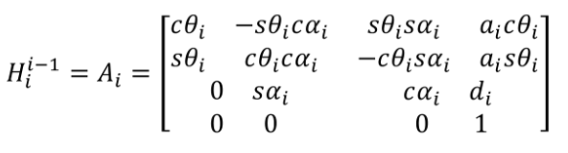

syms th1 th2 th3 th4

L1 = 145;
L2 = 105;
L3 = 105.5;
L4 = 91;

T_01 = [cos(th1) 0 -sin(th1) 0
    sin(th1) 0 cos(th1) 0
    0 -1 0 L1
    0 0 0 1];

T_12 = [cos(th2-pi/2) -sin(th2-pi/2) 0 L2*cos(th2-pi/2)
    sin(th2-pi/2) cos(th2-pi/2) 0 L2*sin(th2-pi/2)
    0 0 1 0
    0 0 0 1];

T_23 = [cos(th3+pi/2) -sin(th3+pi/2) 0 L3*cos(th3+pi/2)
    sin(th3+pi/2) cos(th3+pi/2) 0 L3*sin(th3+pi/2)
    0 0 1 0
    0 0 0 1];

T_34 = [cos(th4) -sin(th4) 0 L4*cos(th4)
    sin(th4) cos(th4) 0 L4*sin(th4)
    0 0 1 0
    0 0 0 1];

T_04 = T_01*T_12*T_23*T_34;

## Simulación

l = [14.5, 10.5, 10.55, 9.1]; % Longitudes eslabones [mm]
% Definicion del robot RTB
L(1) = Link('revolute','alpha',-pi/2, 'a',0,    'd',l(1), 'offset',0,     'qlim',[-3*pi/4 3*pi/4]);
L(2) = Link('revolute','alpha',0,     'a',l(2), 'd',0,    'offset',-pi/2, 'qlim',[-3*pi/4 3*pi/4]);
L(3) = Link('revolute','alpha',0,     'a',l(3), 'd',0,    'offset',pi/2,  'qlim',[-3*pi/4 3*pi/4]);
L(4) = Link('revolute','alpha',0,     'a',l(4), 'd',0,    'offset',0,     'qlim',[-3*pi/4 3*pi/4]);
PhantomX = SerialLink(L,'name','Px');

% roty(pi/2)*rotz(-pi/2)
PhantomX.tool = [1 0 0 l(4); 0 1 0 0; 0 0 1 0; 0 0 0 1];
ws = [-50 50];

% Graficar robot
a=figure(1)
PhantomX.plot([0 0 0 0],'notiles','noname');
%hold on
%trplot(eye(4),'rgb','arrow','length',15,'frame','0')
%axis([repmat(ws,1,2) 0 60])
%PhantomX.teach()

% HOME - [-150 36 -186.6 25.2]

% Pose 1 - [-90.23 -49.51 -157.03 -67.38]

%%
% q = zeros(1,4);
% M = eye(4);
% for i=1:PhantomX.n
%     M = M * L(i).A(q(i));
%     trplot(M,'rgb','arrow','frame',num2str(i),'length',15)
% end

## Nota

`'''`

`ORIGINAL:`

`J1: 150`

`J2: 152.93`

`J3: 62.4`

`J4: 150`

`'''`

`'''`

`HOME:`

`J1: 0`

`J2: 116.89`

`J3: 249.9`

`J4: 124.8`

`'''`

`'''`

`HOME: (ORIGINAL = 0)`

`J1: -150 +`

`J2: -36 -`

`J3: 186.6 -`

`J4: -25.2 -`

`'''`

`'''`

`POSE 2: (ORIGINAL = 0)`

`J1: -90.23 +`

`J2:  49.51 -`

`J3: 157.03 -`

`J4: 67.38 -`

`'''`